# `RangefinderChart`** Examples**

**Overview**

The `RangefinderChart` creates a visualization of bivariate scattered data together with horizontal and vertical lines representing marginal data statistics. Specifically, the chart comprises

- a 2D discrete plot containing the scattered $(x, y)$ data,

- a crosshair indicating the intersection of the marginal medians,

- vertical lines indicating the lower and upper adjacent values for the $x$ data,

- horizontal lines indicating the lower and upper adjacent values for the $y$ data.

The lengths of the lines are given by the marginal interquartile ranges. The *adjacent values* are the nearest data points inside the range determined by the lower and upper values. The *lower and upper values* are 1.5 interquartile ranges outside of the lower and upper quartiles, respectively. 

The chart data comprises numeric vectors `XData` and `YData`.

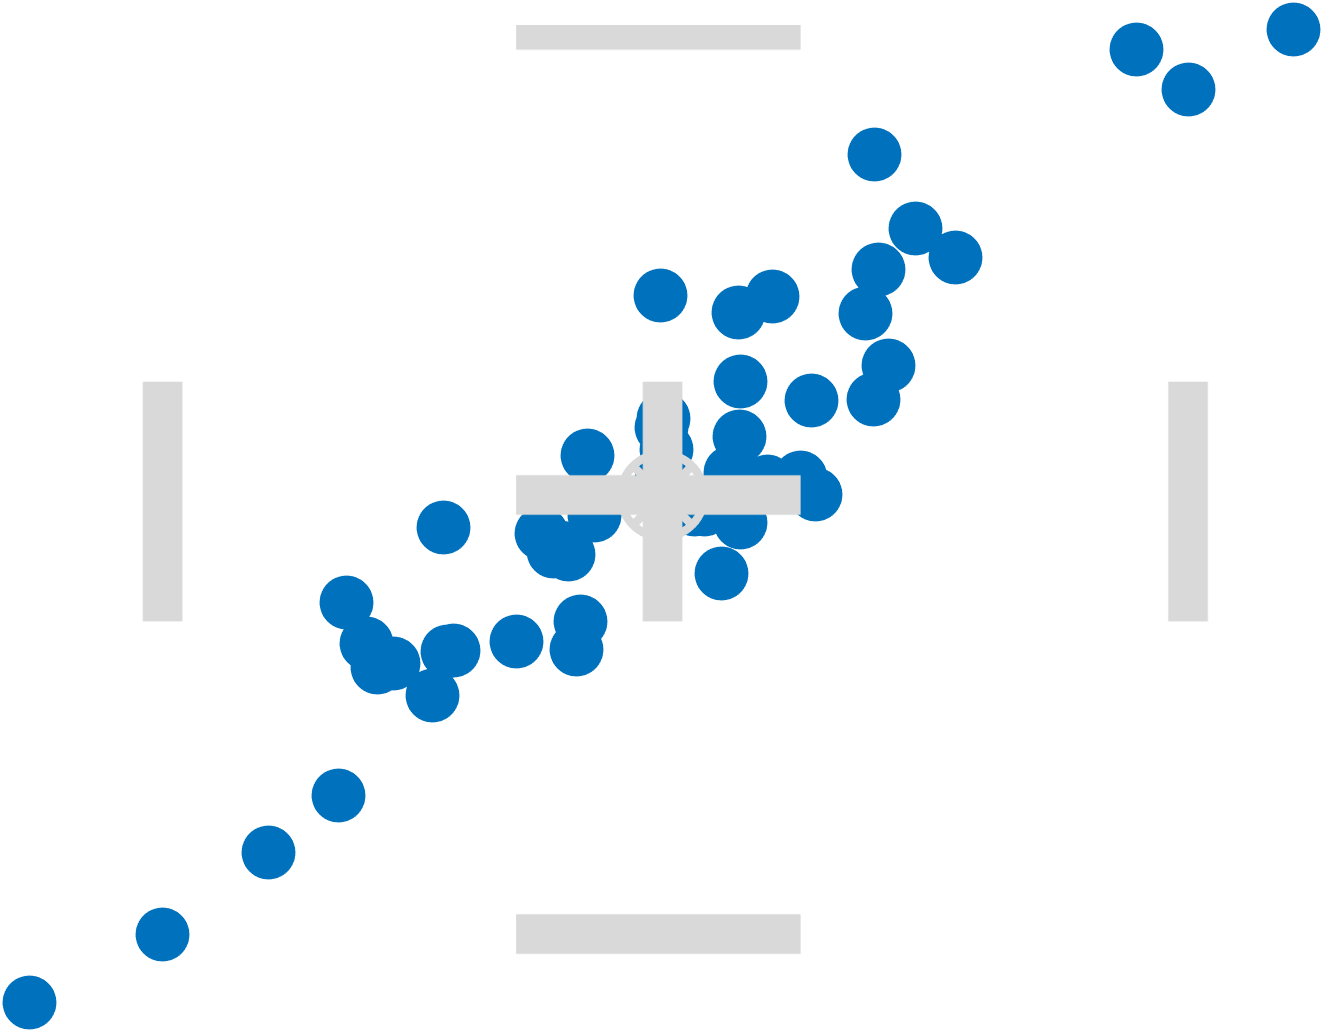

**Resources**

[Open](matlab: edit(fullfile(catalogRoot, "+example", "Rangefinder.mlx"))) this Live Script to run and interact with the examples shown below.

[View](matlab: edit(fullfile(catalogRoot, "+chart", "Rangefinder.m"))) the source code for the `RangefinderChart`.

Martinez, W.L., Martinez, A.R. and Solka, J.L. 2011. *Exploratory Data Analysis with MATLAB (Second Edition), *Chapter 9, Section 9.5 (pp. 356-359). Boca Raton, Florida: Chapman and Hall/CRC Press, Taylor & Francis Group.

## Create sample chart data.

We start by defining sample $x$ and $y$ data vectors for the chart.

numPoints = 1000;
rng( "default" )
x = 2 * randn( numPoints, 1 );
y = 2 * x + 1 + 2 * randn( numPoints, 1 );

## Create a figure for the chart.

f = exampleFigure( "Name", "Rangefinder Example" );

## Create the chart, specifying the parent and input data.

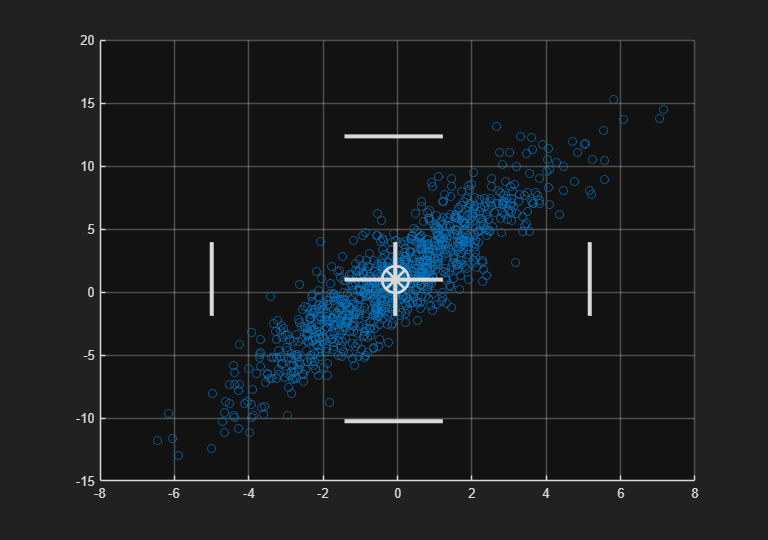

RFC = RangefinderChart( "Parent", f, ...
    "XData", x, ...
    "YData", y );

## Annotate the chart.

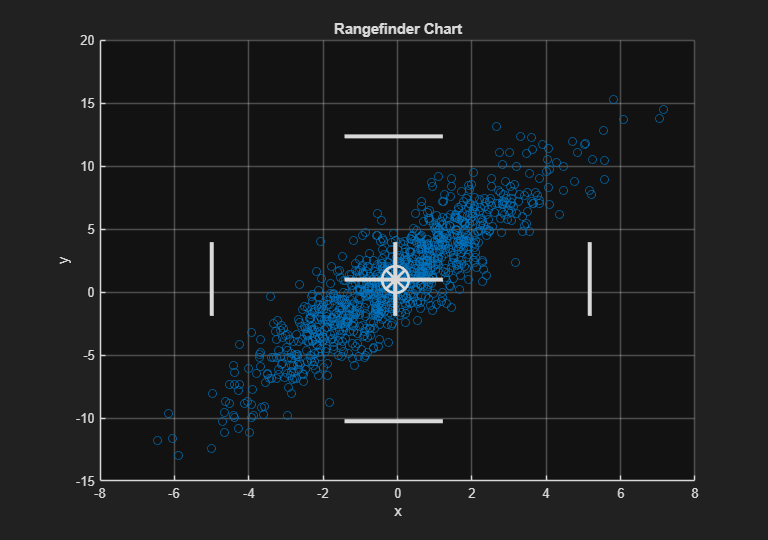

xlabel( RFC, "x" )
ylabel( RFC, "y" )
title( RFC, "Rangefinder Chart" )

## Truncate the $x$-data of the chart.

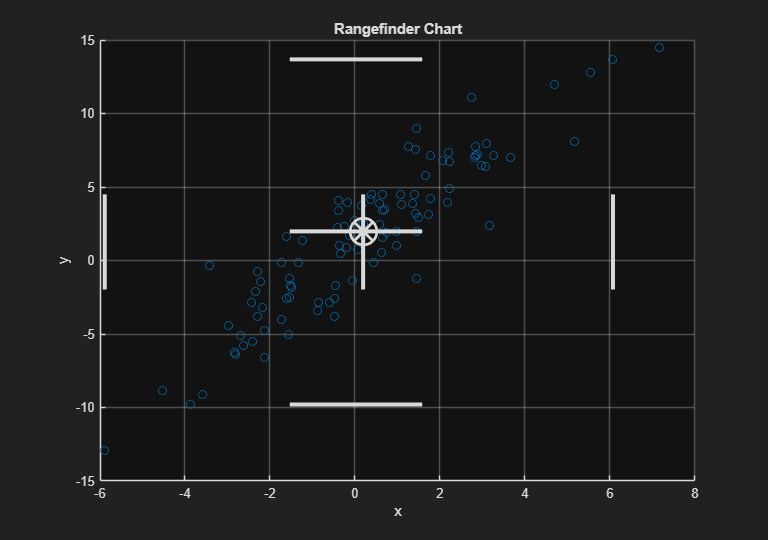

RFC.XData = RFC.XData(1:round(numPoints/10));

## Reinstate the original chart data.

RFC.XData = x;
RFC.YData = y;

## Modify the $y$ data of the chart.

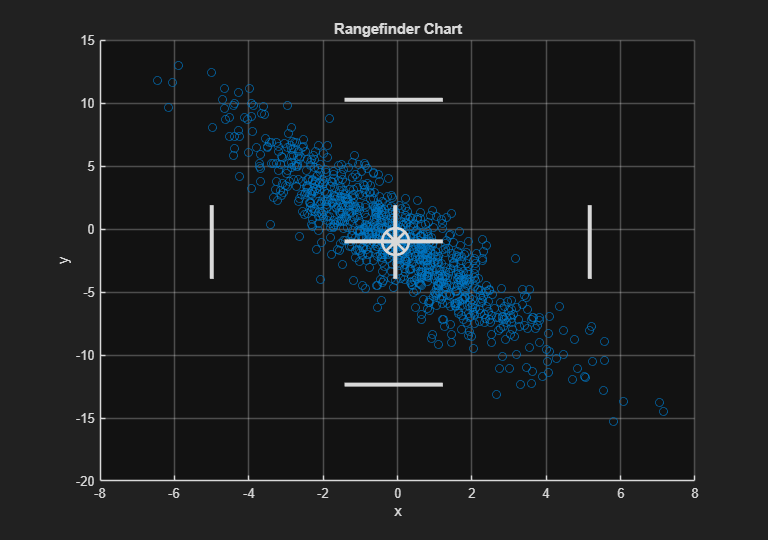

RFC.YData = (-1) * RFC.YData;

## Translate the chart data.

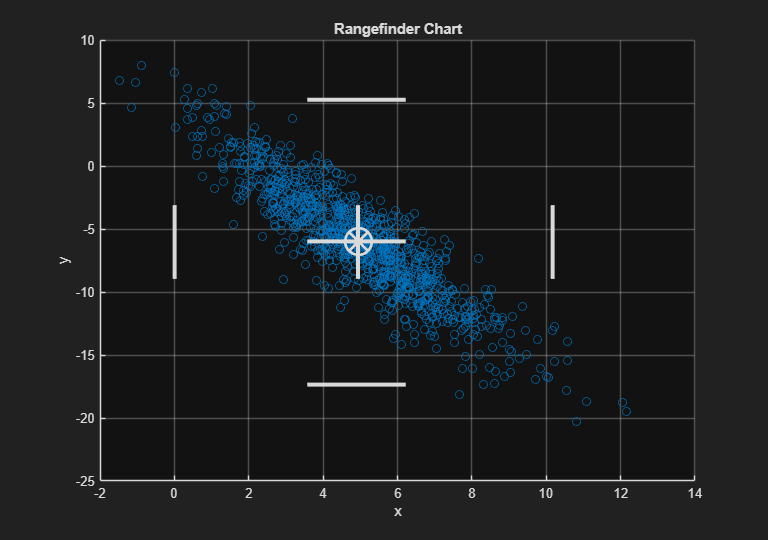

RFC.XData = 5 + RFC.XData;
RFC.YData = -5 + RFC.YData;

## Customize the chart appearance.

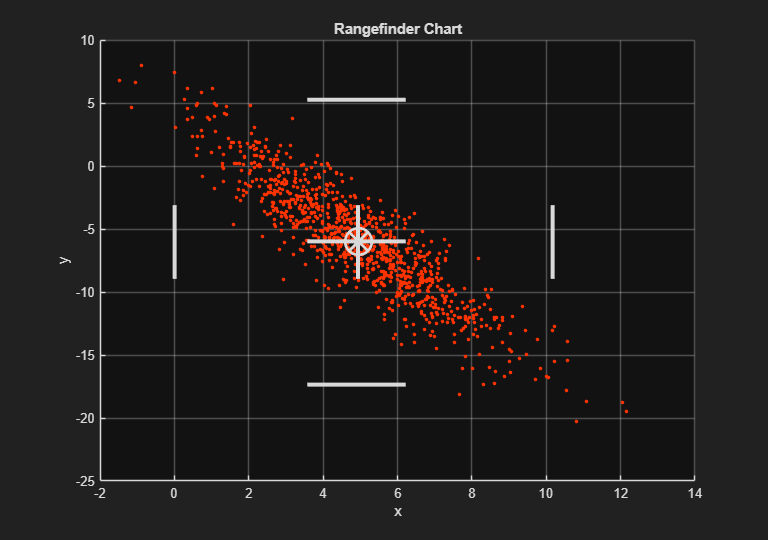

RFC.Marker = ".";
RFC.SizeData = 64;
RFC.CData = [1, 0.2, 0];

*Copyright 2018-2025 The MathWorks, Inc.*